# Data Exploration

In this notebook, we will explore the .csv data corresponding to the dataset which has already been processed with FreeSurfer by us. The aggregated volumes of the different brain regions for each subject is listed in the csv file in the data folder. We will use this to get a first overview of the data with plotting.

## Load the data from the .csv file

[file_name, file_path] = uigetfile(".csv", "Point to the .csv file here.");
measurements = readtable(fullfile(file_path, file_name));

% There's no need to convert age to float - it already is, through
% readtable.

% Optionally convert Sex to categorical.
measurements.Sex = categorical(measurements.Sex);

plotcols = setdiff(measurements.Properties.VariableNames, {'Age', 'Sex', 'Subject'});
% Convert to string to use in the drop-down next.
plotcols = string(plotcols);

## Plot the volumes of the different brain regions across age

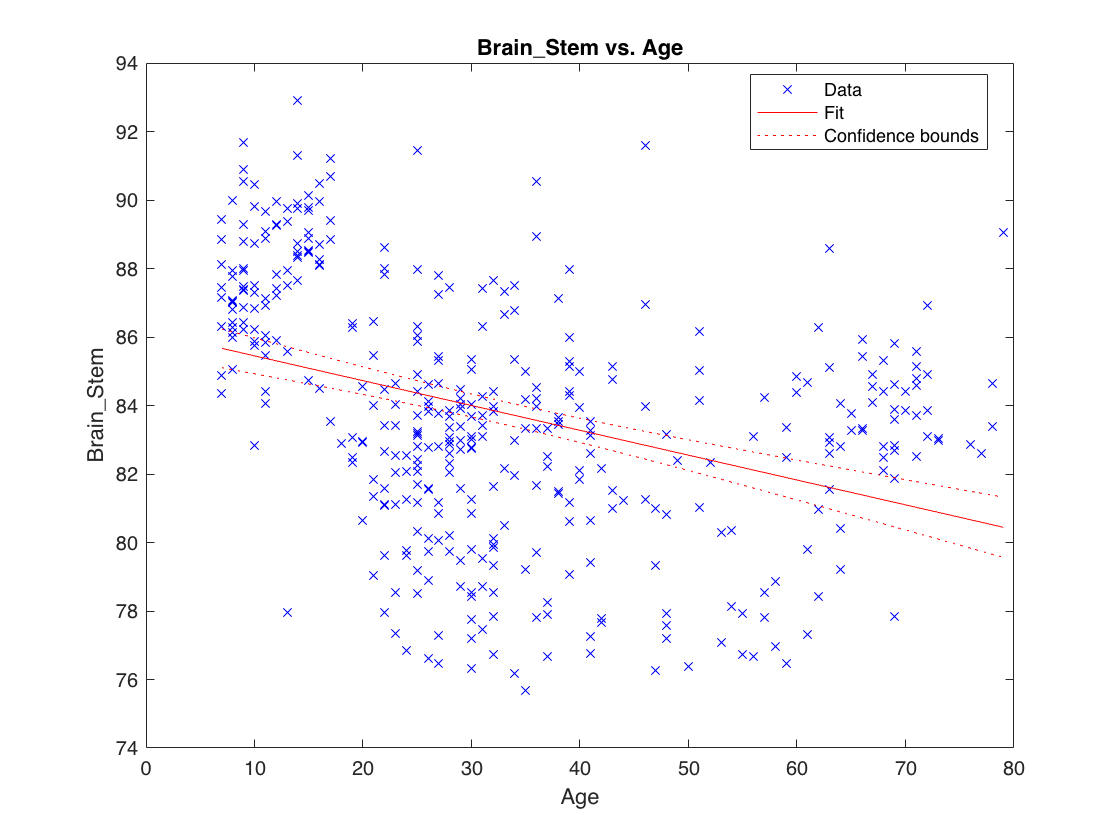

anatomy = plotcols(1);
mdl = fitlm(measurements, anatomy + " ~ Age");

figure, plot(mdl)

## Now stratify the data for men and women to see differences

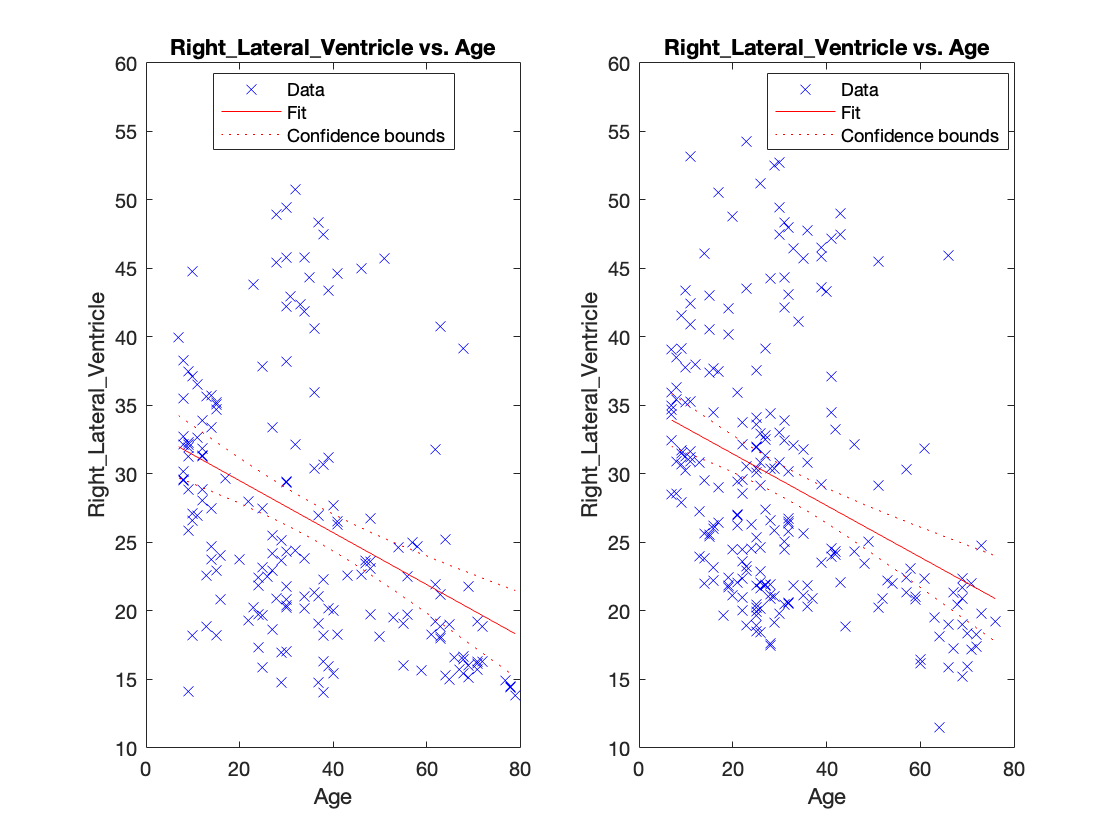

anatomy = plotcols(32);
male_mdl = fitlm(measurements(measurements.Sex == "m", :), anatomy + " ~ Age");
female_mdl = fitlm(measurements(measurements.Sex == "f", :), anatomy + " ~ Age");

figure;
ax_male   = subplot(1,2,1); plot(male_mdl);
ax_female = subplot(1,2,2); plot(female_mdl);
linkaxes([ax_male, ax_female], 'y');

## Check the age distribution for males and females (for example with a boxplot)

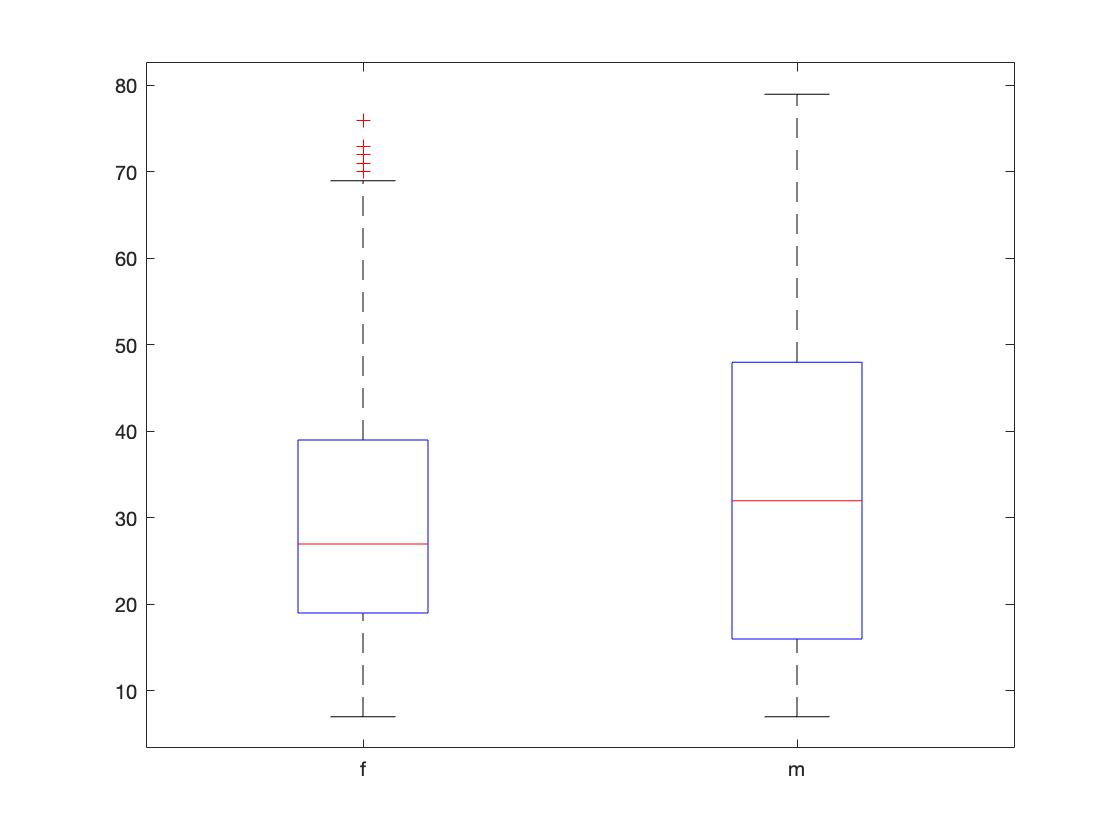

figure, boxplot(measurements.Age, measurements.Sex)